#  Polinomios de Taylor: una aplicación de derivadas a la aproximación de funciones 

[⇦ Menú principal](matlab:open('MainMenu.mlx'))

Quizás hayas notado que las operaciones con polinomios tienen muchas propiedades que las hacen populares para trabajar. Esto significa que hay bastantes situaciones en el mundo real en las que aproximar una función más complicada mediante un polinomio puede dar como resultado una solución rápida y suficientemente buena. Investiguemos algunas de estas aproximaciones. 

**Antes de comenzar: **

Este live script está diseñado para usarse con el código oculto. En la pestaña ** View ** de la barra de herramientas de MATLAB, en la sección ** View **, seleccione ** Hide Code**. Alternativamente, seleccione ** Hide Code ** usando el ícono   en la parte superior derecha del panel Live Editor. 

##  Defina una funcióny un punto 

Considere una función $f(x)$y un punto $x_0$ en el dominio de $f$. Defina su función como `f(x)`y su punto central para la aproximación como `x0`. 

syms F(x) f(x)
F(x) =  x^2*sin(x)-x*cos(x);
x0 =  pi/2;
  

Definiste: 

fexp = F(x);
displayFormula("f(x) = fexp") 

$$f\left(x\right)=x^{2}\,\sin\left(x\right)-x\,\cos\left(x\right)$$

y 

displayFormula("x_0 = x0")

$$x_{0}=\frac{\pi }{2}$$

##  Líneas tangentes 

Probablemente ya hayas encontrado los primeros pasos de este proceso. Si usamos una función constante, $P_0 = a$ , la mejor aproximación alrededor del punto $x_0$ es simplemente evaluar la función: $P_0 = f(x_0)$. Visualmente, esto se ve así: 

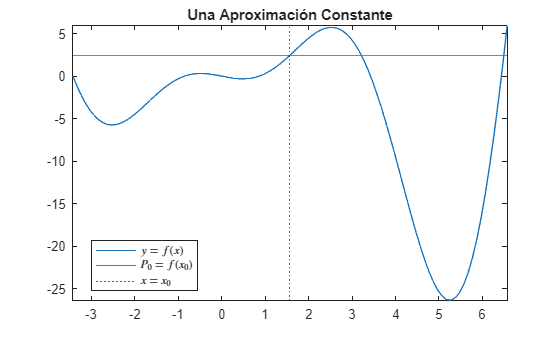

xval = x0-5:.1:x0+5;
clf
plot(xval,F(xval))
hold on
plot([xval(1) xval(end)],[F(x0) F(x0)])
xline(x0,":")
hold off
title("Una Aproximación Constante")
legend(["$y=f(x)$" "$P_0=f(x_0)$" "$x=x_0$"],"Interpreter","latex","Location","best")
axis tight 

Las funciones constantes suelen ser aproximaciones bastante terribles. Podemos obtener una aproximación significativamente mejor si consideramos la mejor aproximación lineal a $f(x)$ alrededor de $x=x_0$. Teóricamente, esto significa: 


$$P_1(x) = ax+b$$
 

con 

$P_1(x_0) = f(x_0)$y $\left.\frac{\text{d}P_1}{\text{d}x}\right|_{x_0} = \left.\frac{\text{d}f}{\text{d}x}\right|_{x_0}$ , 

o en otras palabras 

$P_1 = f(x_0)+f'(x_0)(x-x_0)$. 

La mejor aproximación lineal a una función derivable en un punto es la recta tangente en ese punto. En nuestro ejemplo, esto se convierte en: 

syms dF(x) d f dx
dF(x) = diff(F(x),x);
dfexp = dF(x);
displayFormula("f(x) = fexp") 

$$f\left(x\right)=x^{2}\,\sin\left(x\right)-x\,\cos\left(x\right)$$

y 

displayFormula("df/dx = dfexp") 

$$\frac{\mathrm{df}}{\mathrm{dx}}=x^{2}\,\cos\left(x\right)-\cos\left(x\right)+3\,x\,\sin\left(x\right)$$

por lo que evaluando en $x_0$ tenemos: 

fx0 = F(x0);
dFx0 = dF(x0);
displayFormula("f(x0) = fx0") 

$$f\left(\frac{\pi }{2}\right)=\frac{\pi^{2}}{4}$$

y 

displayFormula("df/dx = dFx0") 

$$\frac{\mathrm{df}}{\mathrm{dx}}=\frac{3\,\pi }{2}$$

Por lo tanto, $P_1 = f(x_0)+f'(x_0)(x-x_0)$ se simplifica a 

syms P(x)
P(x) = F(x0)+dF(x0)*(x-x0);
displayFormula("P_1 = fx0 + (dFx0)*(x-x0)") 

$$P_{1}=\frac{\pi^{2}}{4}+\frac{\pi \,3\,\left(x-\frac{\pi }{2}\right)}{2}$$

o, en forma pendiente-intersección, 

cval = fx0-dFx0*x0;
displayFormula("P_1 = dFx0*x+cval")

$$P_{1}=\frac{\pi \,3\,x}{2}-\frac{\pi^{2}}{2}$$

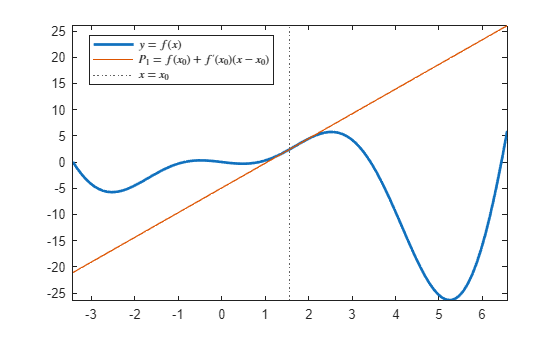

approxLabel = "$P_1 = f(x_0)+f'(x_0)(x-x_0)$";
PlotWithApprox(xval,x0,@(x)F(x),@(x)P(x),approxLabel)

###  Errores 

Con la aproximación constante , en el punto $x=x_1$ la aproximación constante tiene un error de 

$\text{Error} = f(x_1)-P_0(x_1) = f(x_1)-f(x_0)$. 

Con 

x1 = vpa( x0+0.5);  
x1show = double(round(x1,4)); 

este error se convierte en 

fError = double(vpa(F(x1)-F(x0)));
disp("f("+x1show+") - P_0("+x1show+") = " + fError) 

f(2.0708) - P_0(2.0708) = 2.2886


Cuando existe la línea tangente, sin embargo, tiene un error de 


$$\text{Error} = f(x_1)-P_1(x_1)$$
                                    


$$= f(x_1)-\left(f'(x_0)(x_1-x_0) - f(x_0)\right)$$



$$= f(x_1)-f(x_0) - f'(x_0)(x_1-x_0)$$
   

que se garantiza que será pequeño para valores de $x_1$ cercanos a $x_0$. En este caso, el error es 

linError = double(vpa(F(x1)-P(x1)));
disp("f("+x1show+") - P_1("+x1show+") = " + linError)

f(2.0708) - P_1(2.0708) = -0.067556


#### ** Ejercicio 1: ** Rectas tangentes 

Dada una función, $f(x)$y un punto $x_0$ , calcula la recta tangente a $y=f(x)$ en el punto $x=x_0$. Tu solución debería ser $P(x)$. 

clear MyFun VarChoice
syms F(x) dF(x) d P(x) Psoln(x) x
num = randi([-10,10]);
idx = randi(7);
opts = [1 1 1 1 2 3 4];
x0 = num/opts(idx);
[MyFun,VarChoice,~] = GenFun(x,1);  % GenFun está definido en FunctionLibrary   
F(x) = MyFun;
dF(x) = diff(F(x),x);
while imag(double(F(x0))) ~= 0 || imag(double(dF(x0))) ~= 0
    [MyFun,VarChoice,~] = GenFun(x,1);  % GenFun está definido en FunctionLibrary   
    F(x) = MyFun;
    dF(x) = diff(F(x),x);
end
displayFormula("f(VarChoice) = MyFun")
if mod(double(F(pi)),1) == 0
    x0 = x0*pi;
end
xVal = x0-5:0.1:x0+5;
displayFormula("x_0 = x0")
Psoln(x) = F(x0)+dF(x0)*(x-x0); 

P(x) =  0;
 
PlotWithApprox(xVal,x0,@(x)F(x),@(x)P(x),"My tangent line, $P(x)$")
CheckPofx(@(x)P(x),@(x)Psoln(x),x0)

##  Aproximaciones cuadráticas 

¿Por qué detenernos con aproximaciones lineales? Calculemos la mejor aproximación cuadrática a nuestra función $f(x)$ alrededor del punto $x= x_0$.Considere una función cuadrática general, $P_2 = a(x-x_0)^2+b(x-x_0)+c$. Entonces $P_2(x_0) = f(x_0)$ implica que $c = f(x_0)$. También tenemos la misma condición que $\left.\frac{\text{d}P_2}{\text{d}x}\right|_{x_0} = b = f'(x_0)$. La condición final es que $\left. \frac{\text{d}P_2}{\text{d}x^2}\right|_{x_0} = 2a = f''(x_0)$.Por lo tanto, $a = \frac{f''(x_0)}{2}$ ,y la aproximación cuadrática a $f(x)$ en $x_0$ es 


$$P_2 = \frac{f''(x_0)}{2}(x-x_0)^2 + f'(x_0)(x-x_0) +f(x_0)$$
 

que también es 


$$P_2 = \frac{f''(x_0)}{2}(x-x_0)^2 + P_1.$$
                              

** Ejercicio 2: Aproximación cuadrática **

Encuentra la aproximación cuadrática a $y = e^x$ alrededor del punto $x = 0$. Su aproximación debería ser $P(x)$. 

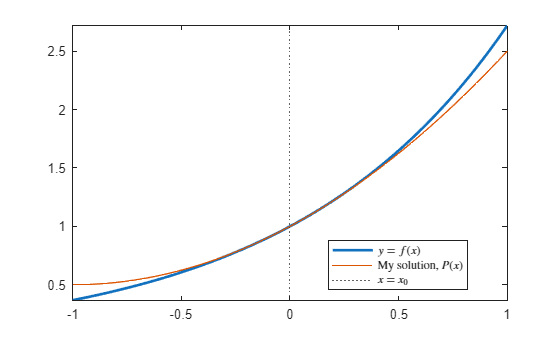

syms P(x)
P(x) =   exp(0)/2*(x-0)^2+exp(0)*(x-0)+exp(0);
 
PlotWithApprox(-1:0.02:1,0,@(x)exp(x),@(x)P(x),"My solution, $P(x)$")

CheckPPofx(@(x)P(x))

Tienes el valor correcto para f(0)
Tienes el valor correcto para f'(0)
Tienes el valor correcto para el término cuadrático, a.
Tu solución para la aproximación cuadrática es correcta.


##  Aproximación de orden superior 

Podemos continuar ampliando estos cálculos a aproximaciones de orden superior. Una aproximación de quinto grado, por ejemplo, sería: 


$$P_5(x) = a_0 + a_1(x-x_0)+a_2(x-x_0)^2+a_3(x-x_0)^3 + a_4(x-x_0)^4 + a_5(x-x_0)^5$$


y $P_5(x)$ deben concordarcon la función $f(x)$ que estamos tratando de aproximary con tantas derivadas como sea posible. 


$$P_5(x_0) = f(x_0) \Rightarrow a_0 = f(x_0)$$



$$P_5'(x_0) = f'(x_0) \Rightarrow a_1 = f'(x_0)$$



$$P''_5(x_0) = f''(x_0) \Rightarrow 2a_2 = f''(x_0)$$



$$\left.\frac{\text{d}^3P_5}{\text{d}x^3}\right|_{x_0} = \left.\frac{\text{d}^3f}{\text{d}x^3}\right|_{x_0} \Rightarrow 6a_3 = \left.\frac{\text{d}^3f}{\text{d}x^3}\right|_{x_0}$$



$$\left.\frac{\text{d}^4P_5}{\text{d}x^4}\right|_{x_0} = \left.\frac{\text{d}^4f}{\text{d}x^4}\right|_{x_0} \Rightarrow 24a_4 = \left.\frac{\text{d}^4f}{\text{d}x^4}\right|_{x_0}$$



$$\left.\frac{\text{d}^5P_5}{\text{d}x^5}\right|_{x_0} = \left.\frac{\text{d}^5f}{\text{d}x^5}\right|_{x_0} \Rightarrow 120a_5 = \left.\frac{\text{d}^5f}{\text{d}x^5}\right|_{x_0}$$


** Ejercicio 3: Aproximación de orden superior **

a) Calcule la aproximación de quinto grado $P_5(x)$ para $f(x) = \sin(x)$ alrededor de $x_0 = 0$. 

syms P5f(x) 
P5f(x) =   sin(0)+cos(0)*x-sin(0)/2*x^2-cos(0)/6*x^3+sin(0)/24*x^4+cos(0)/120*x^5; 

b) Calcule la aproximación de cuarto grado $P_4(x)$ para $g(x) = 3x^2-2x+7$ alrededor de $x_0 = -1$. 

syms P4g(x) 
P4g(x) =   3*x^2-2*x+7; 

c) Calcule la aproximación de tercer grado $P_3(x)$ para $h(x) = \ln(x)$ alrededor de $x_0 = 1$. 

syms P3h(x)
P3h(x) =   log(1)+(1/1)*(x-1)-(1/1^2)/2*(x-1)^2+(2/1^3)/6*(x-1)^3;
CheckHigherOrderApprox(@(x)P5f(x),@(x)P4g(x),@(x)P3h(x))

Tu solución para la parte a) es correcta.
Tu solución para la parte b) es correcta.
Tu solución para la parte c) es correcta.


** Práctica adicional: creay resuelve tus propios problemas **

Plantea el problema: 

syms x f(x) Pn(x)
f(x) =  log(x);
x0 =  2;
n = 4; 

Resuelve el problema de encontrar $P_n(x)$ para $f(x)$ alrededor de un centro $x_0$. 

Pn(x) =   log(2)+(1/2)*(x-2)-(1/8)*(x-2)^2+(1/24)*(x-2)^3-(1/64)*(x-2)^4;
 
CheckMyApprox(@(x)f(x),x0,n,@(x)Pn(x));

Has resuelto el problema correctamente.


##  Polinomios de Taylor 

Considere el polinomio de Taylor $n^{\text{th}}$, $P_n(x)$ , definido como: 


$$P_n(x) = f(x_0) + \left. \frac{\text{d} f}{\text{d} x} \right|_{x_0} (x - x_0) + \left. \frac{\text{d}^2 f}{\text{d} x^2} \right|_{x_0} (x - x_0)^2 + \ldots + \left. \frac{\text{d}^n f}{\text{d} x^n} \right|_{x_0} (x - x_0)^n.$$


Podemos visualizar la aproximación resultante: 

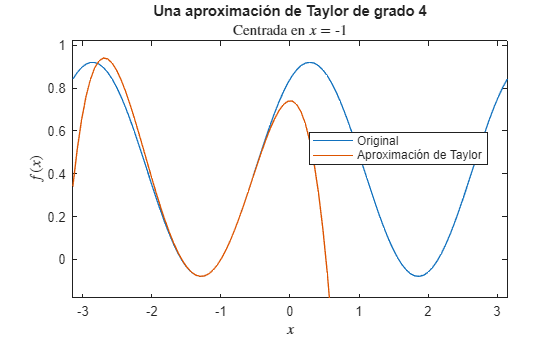

syms F(x) 
F(x) = sin(x+1)*cos(x);
x0 = -1;
deg = 4;
bds = [-pi,pi];
 
if deg<0 || mod(deg,1) ~= 0
    disp("Please select a non-negative integer degree, n.")
else
    try
        currentProject;
        T = ShowTaylor(@(x)F(x),deg,bds,x0);
    catch
        addpath("FunctionLibrary")
        T = ShowTaylor(@(x)F(x),deg,bds,x0);
        rmpath("FunctionLibrary")
    end
end

oldPrefs = sympref();          % Guarde las preferencias del usuario actual para restablecerlas al final de la sección
sympref('PolynomialDisplayStyle','ascend');  % Presentar polinomios en formato de potencia descendente.
sympref('FloatingPointOutput',false);         % No utilice representaciones de punto flotante
displayFormula("P_n(x) = T")

$$P_{n}\left(x\right)=\sin\left(1\right)\,{\left(1+x\right)}^{2}-\frac{\sin\left(1\right)\,{\left(1+x\right)}^{4}}{3}+\cos\left(1\right)\,\left(1+x\right)-\frac{2\,\cos\left(1\right)\,{\left(1+x\right)}^{3}}{3}$$

sympref(oldPrefs);   % Restaure las preferencias del sistema que tenía antes de ejecutar este script.

 ** Refleje **. 

- Investigue las aproximaciones del polinomio de Taylor para $\sin(x)$y $\cos(x)$. ¿Tiene una teoría de por qué $\sin(x)$ es una función impary $\cos(x)$ es una función par? 

###  Animar la aproximación mediante polinomios de Taylor 

Visualice la mejora en la aproximación a medida que crece el orden del polinomio utilizado. 

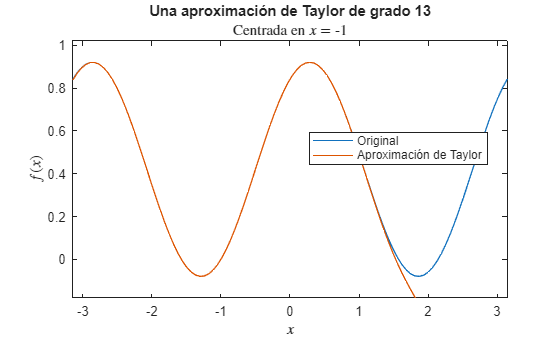

if ~exist("bds","var")
    syms F(x)
    F(x) =  sin(x)/x-x*cos(x);
    x0 =  0;
    bds = [-3*pi,3*pi];
    disp("Usando valores predeterminados con f(x) = x*sin(x)-cos(x)/x y x0=0.")
end
 
finalValue = 13;
try
    currentProject;
    Tlast = ShowTaylor(@(x)F(x),1:finalValue,bds,x0);
catch
    addpath("FunctionLibrary")
    Tlast = ShowTaylor(@(x)F(x),1:finalValue,bds,x0);
    rmpath("FunctionLibrary")
end

showT = true;
if showT
    displayFormula("P_n(x) = Tlast",["n","Tlast"],[finalValue,Tlast])
end

$$P_{n}\left(x\right)=\sin\left(1\right)\,{\left(x+1\right)}^{2}-\frac{\sin\left(1\right)\,{\left(x+1\right)}^{4}}{3}+\frac{2\,\sin\left(1\right)\,{\left(x+1\right)}^{6}}{45}-\frac{\sin\left(1\right)\,{\left(x+1\right)}^{8}}{315}+\frac{2\,\sin\left(1\right)\,{\left(x+1\right)}^{10}}{14175}-\frac{2\,\sin\left(1\right)\,{\left(x+1\right)}^{12}}{467775}+\cos\left(1\right)\,\left(x+1\right)-\frac{2\,\cos\left(1\right)\,{\left(x+1\right)}^{3}}{3}+\frac{2\,\cos\left(1\right)\,{\left(x+1\right)}^{5}}{15}-\frac{4\,\cos\left(1\right)\,{\left(x+1\right)}^{7}}{315}+\frac{2\,\cos\left(1\right)\,{\left(x+1\right)}^{9}}{2835}-\frac{4\,\cos\left(1\right)\,{\left(x+1\right)}^{11}}{155925}+\frac{4\,\cos\left(1\right)\,{\left(x+1\right)}^{13}}{6081075}$$

##  Exploración adicional: [Serie Taylor](https://www.mathworks.com/help/symbolic/taylor-series.html)

Si llevamos esto al límite y permitimos un número infinito de términos en nuestra suma, tenemos la expresión: 


$$f(x_0) + \sum_{i=1}^{\infty} \left.\frac{\text{d}^if}{\text{d}x^i}\right|_{x_0} (x-x_0)^i$$


De hecho, para funciones suficientemente agradables, llamadas * funciones analíticas * , esta expresión converge al valor de la función misma: 


$$f(x) = f(x_0) + \sum_{i = 1}^\infty \left. \frac{\text{d}^if}{\text{d}x^i} \right|_{x_0} (x - x_0)^i$$


[⇦ Menú principal](matlab:open('MainMenu.mlx'))

## Funciones auxiliares locales 

 Si desea ver los detalles del código, seleccione la pestaña **View** y cambie a **Output inline**. Como alternativa, seleccione** Output inline** usando el ícono   en la parte superior derecha del panel Live Editor. 

`PlotWithApprox(xval,x0,Fh,dFh,approxLabel)`

Cree una gráfica de la función original $y = \text{Fh}(x)$ sobre el dominio dado por `xval`. Coloque encima de eso un gráfico de $y=\text{dFh}(x)$ sobre el mismo dominio. El argumento final, `approxLabel` , proporciona la etiqueta utilizada en la leyenda de la función $y=\text{dFh}(x)$. 

function PlotWithApprox(xval,x0,Fh,dFh,approxLabel)
clf
plot(xval,double(Fh(xval)),"LineWidth",2)
hold on
plot(xval,double(dFh(xval)))
xline(x0,":")
hold off
legend(["$y=f(x)$" approxLabel "$x=x_0$"],"Interpreter","latex","Location","best")
axis tight
end
 

`CheckPofx(Ph,Psolnh,x0)`

Esta función comprueba si las expresiones `Ph`y `Psolnh` coinciden como se supone que deben hacerlo. Muestra comentarios de "crédito parcial" si algunos de los cálculos coinciden, además de señalar la corrección o incorrección de toda la solución. 

function CheckPofx(Ph,Psolnh,x0)
syms x
flag = [0 0];
    if abs(double(Ph(x0) - Psolnh(x0))) < 4*eps
        disp("Tienes el valor correcto para f("+x0+")")
        flag(1) = 1;
    else
        disp("Tienes un valor incorrecto para f("+x0+")")
    end
    if abs(double(diff(Ph(x),x)-diff(Psolnh(x),x)))<4*eps
        disp("Tienes el valor correcto para f'("+x0+")")
        flag(2) = 1;
    else
        disp("Tienes un valor incorrecto para f'("+x0+")")
    end

flag = logical(flag);

if all(flag)
    disp("Tu solución para la línea tangente es correcta.")
else
    disp("Tu solución para la línea tangente es incorrecta. Por favor, intenta de nuevo.")
end
end 

`CheckPPofx(Ph)`

Una versión modificada de CheckP `ofx` que verifica las soluciones ofrecidas al Ejercicio 2. 

function CheckPPofx(Ph)
syms x
x0 = 0;
flag = [0 0 0];
    if abs(double(Ph(x0) -1)) < 4*eps
        disp("Tienes el valor correcto para f("+x0+")")
        flag(1) = 1;
    else
        disp("Tienes un valor incorrecto para f("+x0+")")
    end
    if abs(double(subs(diff(Ph(x),x)-1,x,0)))<4*eps
        disp("Tienes el valor correcto para f'("+x0+")")
        flag(2) = 1;
    else
        disp("Tienes un valor incorrecto para f'("+x0+")")
    end
    if abs(double(diff(Ph(x),2)-1))<4*eps
        disp("Tienes el valor correcto para el término cuadrático, a.")
        flag(3) = 1;

    elseif abs(double(diff(Ph(x),x,2)/2-1))<4*eps
        disp("Tienes un valor incorrecto para el término cuadrático, a.")
        disp("¿Quizás olvidaste dividir por 2?")
    else
        disp("Tienes un valor incorrecto para el término cuadrático, a.")
    end
flag = logical(flag);

if all(flag)
    disp("Tu solución para la aproximación cuadrática es correcta.")
else
    disp("Tu solución para la cuadrática es incorrecta. Por favor, intenta de nuevo.")
end
end 

`CheckHigherOrderApprox(P1,P2,P3)`

Esta función verifica que las soluciones del Ejercicio 3 sean correctas llamando a una función auxiliar que verifica cada derivada. 

function CheckHigherOrderApprox(P1,P2,P3)
CheckDers(P1,[0 1 0 -1 0 1],0, "a)");
CheckDers(P2,[12 -8 6 0 0],-1,"b)");
CheckDers(P3,[0 1 -1 2],1,"c)");
end 

`CheckMyApprox(f,x0,n,Pn)`

Esta función calcula los argumentos apropiados para pasar a CheckD `ers` para evaluar si la solución a la práctica adicional autodefinida es correcta. 

function CheckMyApprox(f,x0,n,Pn)
syms x
pSoln = nan([1 n+1]);
pSoln(1) = double(f(x0));
for k = 1:n
    dkf = diff(f(x),x,k);
    pSoln(k+1) = subs(dkf,x0);
end
CheckDers(Pn,pSoln,x0,"extra");
end 

`CheckDers(P,pSoln,x0,partLabel)`

Esta función verifica las derivadas de la solución propuesta `P`con los valores esperados definidos por `pSoln` en el punto `x0`. El valor de entrada `partLabel` se utiliza para identificar qué componente del ejercicio se está verificando actualmente para que la retroalimentación se pueda proporcionar correctamente. 

function flag = CheckDers(P,pSoln,x0,partLabel)
syms x
flag = 1;
p0 = pSoln(1);
pRest = pSoln(2:end);
if P(x0) ~= p0
    flag = 0;
else
    for k = 1:length(pRest)
        dkP = diff(P(x),x,k);
        if abs(double(subs(dkP,x0))-pRest(k)) > 4*eps && flag == 1
            flag = 0;
        end
    end
end

if partLabel ~= "extra"
    if flag == 1
        disp("Tu solución para la parte " + partLabel + " es correcta.")
    else
        disp("Tu solución para la parte " + partLabel + " es incorrecta.")
        disp("Por favor, intenta " + partLabel + " de nuevo.")
    end
else
    if flag == 1
        disp("Has resuelto el problema correctamente.")
    else
        disp("No, esa no es la solución correcta. Por favor, intenta de nuevo.")
        disp("Probablemente quieras revisar tus derivadas y tus signos.")
    end
end
end